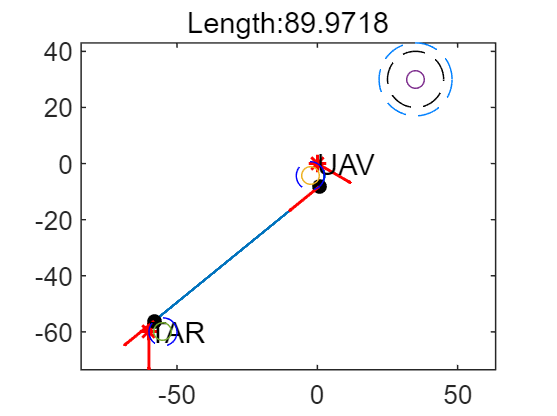

clear all
%% 定义函数输入
Start_Point = [0,0,transform_theta(-pi/6)];
End_Point = [-60,-60,transform_theta(pi*3/2)];
r=5;
sure=3;
R=10+sure;

Stepsize=0.01;
Avoid_Center = [35,30];

%% 寻找Dubins路径
[param_all,param_best] = DubinsAvoid(Start_Point, End_Point,Avoid_Center,r,R,Stepsize);
figure(1)
DrawD_bset(param_best,sure)

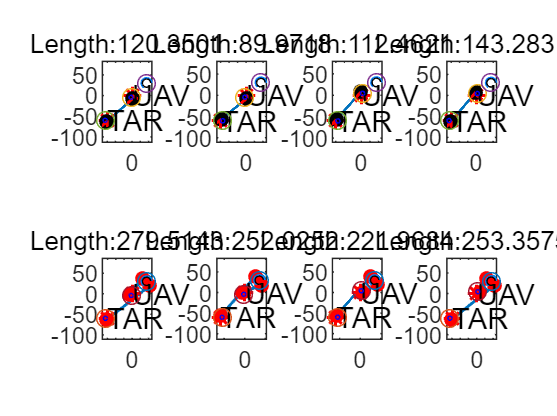


% figure(2)
% for i=1:4
%     for j=1:2
%         DrawD_bset(param_all(j,i))
%     end
% end

figure(2)
hold on
for j=1:2
    for i=1:4
        subplot(2,4,i+4*(j-1));
        DrawD_bset(param_all(j,i),sure)
    end
end

% subplot(2,2,1);
% plot(param_all(2,1).path(1,:),param_all(2,1).path(2,:),'LineWidth',1.3,'Color',[0,0,1]);
% axis equal;
% subplot(2,2,2);
% plot(param_all(2,2).path(1,:),param_all(2,2).path(2,:),'LineWidth',1.3,'Color',[0,0,1]);
% axis equal;
% subplot(2,2,3);
% plot(param_all(2,3).path(1,:),param_all(2,3).path(2,:),'LineWidth',1.3,'Color',[0,0,1]);
% axis equal;
% subplot(2,2,4);
% plot(param_all(2,4).path(1,:),param_all(2,4).path(2,:),'LineWidth',1.3,'Color',[0,0,1]);
% axis equal;
